# PNNL Chemometric Methods

Copyright 2022 Battelle Memorial Institute

## Classical Least Squares (CLS)

Classical least squares computes $C_\textrm{cls}$ that minimizes $||CK_\textrm{cls}-A_\textrm{unkown}||_2$, where $CK=A$ is the Beer's law relationship between concentration $C$, extinction coefficient $K$, and absorbtion $A$.  Multiplier matrix $B_\textrm{cls}$ is the pseudo-inverse of Beer's law extinction coefficient matrix $K_\textrm{cls}$ such that $C_\textrm{cls} = A_\textrm{unknown} \cdot B_\textrm{cls}$.  The CLS algorithm is encapsulared in function `pnnl_cls`.

## Principal Component Regression (PCR)

Principal component regression computes $C_\textrm{pcr}$ using $C_\textrm{train}$ and the first $r$ principal components of $A_\textrm{train}$.  The PCR algorithm is encapsulated in function `pnnl_pcr`.

## Partial Least Squares (PLS)

Partial least squares computes $C_\textrm{pls}$ using the weights from the SIMPLS algorithm with $r$ latent variables. The PLS algorithm without mean centering is encapsulated in function `pnnl_pls`.

## Napalm Data

Load the included napalm data to run the CLS, PCR, and PLS algorithms.

clearvars
load pnnl_napalm_data
whos

  Name                     Size               Bytes  Class     Attributes

  A_train                 20x1713            274080  double              
  A_unknown               12x1713            164448  double              
  C_train                 20x3                  480  double              
  C_validation            12x3                  288  double              
  ConcentrationUnits       1x4                    8  char                
  ConstituentNames         1x3                  364  cell                
  WavenumberLabel          1x20                  40  char                
  Wavenumbers              1x1713             13704  double              
  ans                      1x1                    8  double              



For example, predict $C_\textrm{pcr}$ with 3 principal components.

C_pcr = pnnl_pcr(A_train, C_train, A_unknown, 3)

C_pcr =    12.9651   41.5598   48.0989
   11.3438   43.0304   49.0159
   13.3397   40.7442   47.5971
   20.1845   39.9731   44.0269
   20.8106   34.9763   45.9648
   15.0783   37.3312   51.0697
   14.2210   39.6347   49.2717
   14.8666   38.2302   49.9465
   20.3575   40.8076   42.7753
   19.5111   41.4280   41.7355


### Examine the Data

It's a good idea to look at the data before analyzing it.

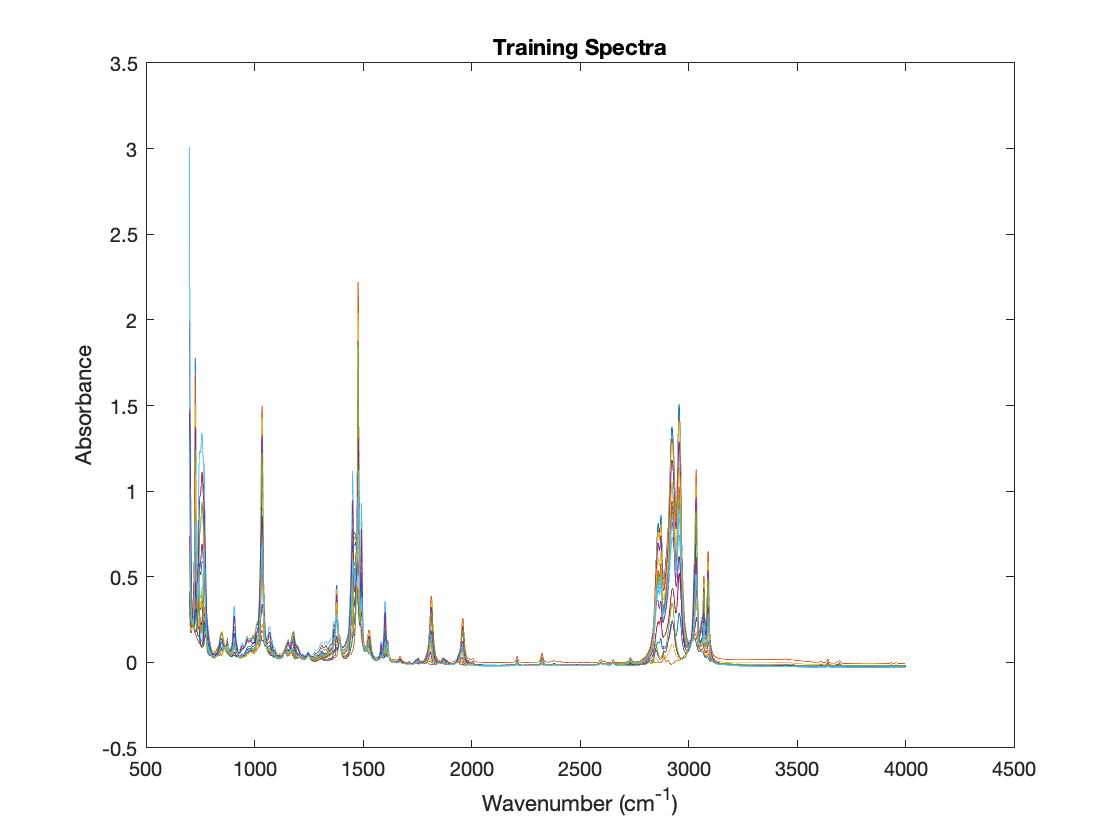

plot(Wavenumbers,A_train)
xlabel(WavenumberLabel)
ylabel('Absorbance')
title('Training Spectra')

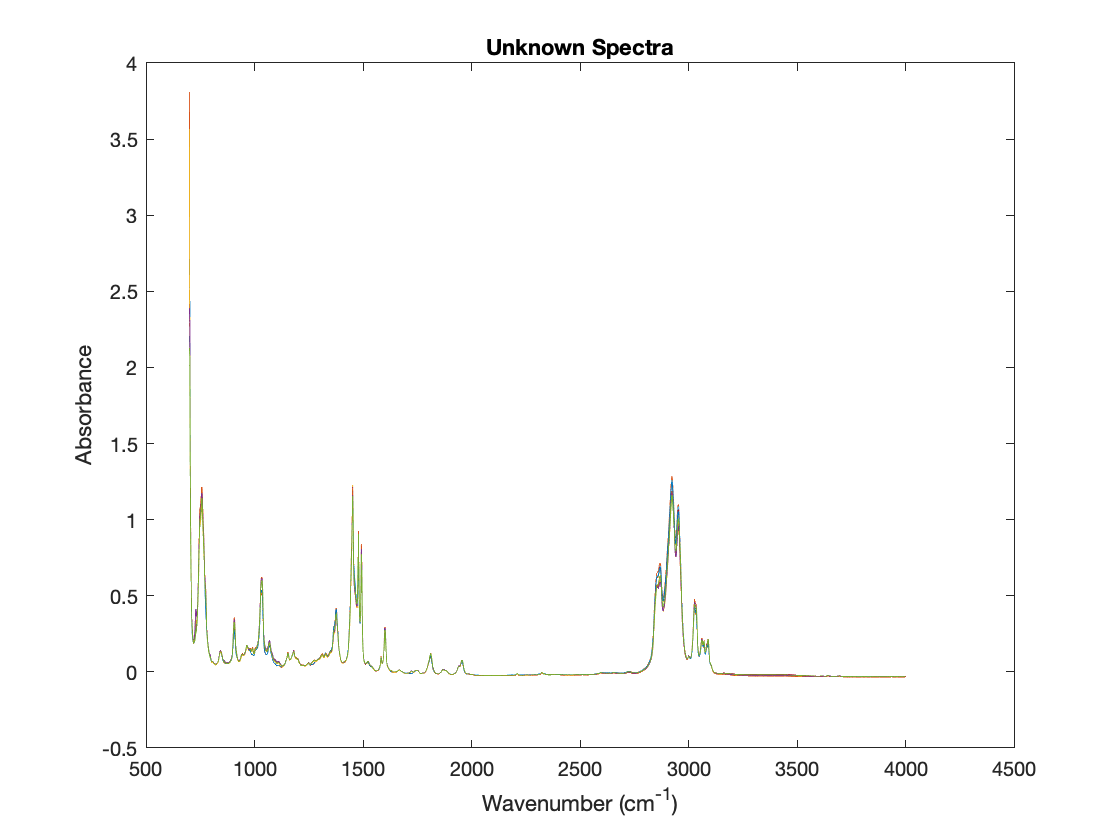

plot(Wavenumbers,A_unknown)
xlabel(WavenumberLabel)
ylabel('Absorbance')
title('Unknown Spectra')

## Root Mean Square Error (RMSE)

The root mean square error of the prediction $C_\textrm{pcr}$ is $\textrm{RMSEP} = \sqrt{\textrm{mean}\left((C_\textrm{pcr}-C_\textrm{validation}).^2\right)}$.  The RMSE algorithm is encapsulated in function `pnnl_rmse`.  Using `vecnorm` is theoretically equivalent, but is better than computing the square and square root with respect to very large or very small numbers.

The columns correspond to the RMSEP of the compnents benzene, polystyrene, and gasoline.

RMSEP_pcr = pnnl_rmse(C_pcr, C_validation) %#ok<*NASGU> 

RMSEP_pcr =     7.7847    2.2831    9.9695


## Calibration Predictions

### Training

You can run a predictor method against the training data.

C_pcr_train = pnnl_pcr(A_train, C_train, A_train, 3);
RMSEC = pnnl_rmse(C_pcr_train, C_train)

RMSEC =     4.2787    2.3856    5.6681


### Cross-validation

You can cross-validate by running a predictor method against the training data.  For each of the rows in the training set, leave one row out, and use that row as the unknown data.  The `pnnl_cross_validation` function encapsulates this, 

where method is a function handle, 

or

or

and the variable input argument `varargin` is the number of principal components for PCR or the number of latent variables for PLS.

For example

C_pcr_cross_validation = pnnl_cross_validation(@pnnl_pcr, A_train, C_train, 3);
RMSECV = pnnl_rmse(C_pcr_cross_validation, C_train)

RMSECV =     5.1022    2.9924    6.7526


## Plot the concentration results

Plot the results of $C_\textrm{validation}$ against $C_\textrm{pcr}$ using a scatter plot

figure
plot(C_validation,C_pcr,'.','MarkerSize',35);

Save the color order of the constituents to coordinate the colors of the training and cross-validation data.

colorOrder = get(gca,'ColorOrder');

Hold the axis and plot the training and cross-validation sets.

hold on

Plot training prediction with `o` marker.

plot(C_train,C_pcr_train,'o','MarkerSize',10,'LineWidth',1)

Plot cross-validation concentrations with `+` marker.

plot(C_train,C_pcr_cross_validation,'+','MarkerSize',10,'LineWidth',1)

Draw a 1-1 line.

line(C_train,C_train,'Color','k');

Reset the color order so the training and cross-validation sets have the same colors for their constituents.

n = size(C_validation,2);
set(gca,'ColorOrder',colorOrder(1:n,:));

Create a legend and make the axis square, so you can see that the training line is 45 degrees.

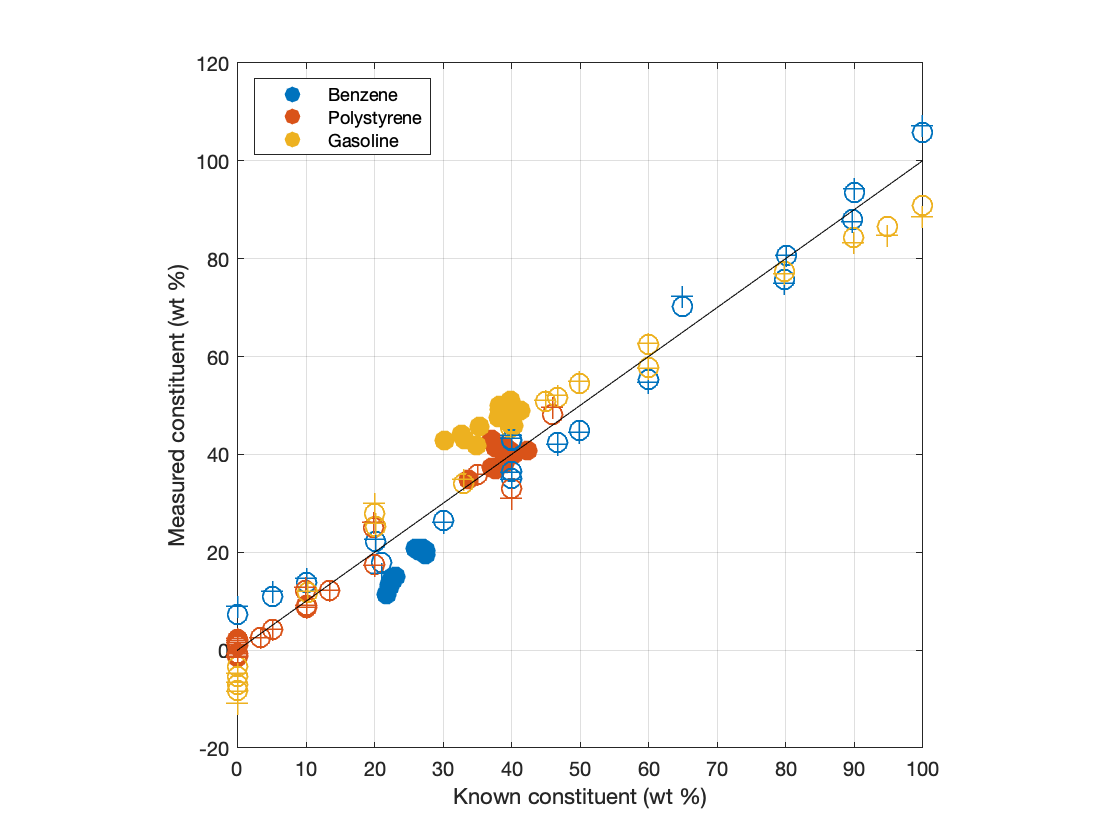

legend(ConstituentNames{:},'Location','northwest')
xlabel('Known constituent (wt %)')
ylabel('Measured constituent (wt %)')
axis square
grid on
box on

Unknown prediction is displayed as a solid dot.  Training predicition is displayed as an open circle.  Cross-validation prediction is displayed as a plus sign.

## Functions that load napalm data, predict, and plot

The following functions encapsulate the steps in the previous sections for each of the methods.  They load the napalm data, predict and plot the concentration matrices, and display the RMSE values.

### Plotting

If you call them with no output arguments, then the plots and displays are shown.  If you input a vector to PCR and PLS, then they are run for the number of principal components or latent variables, respectively.

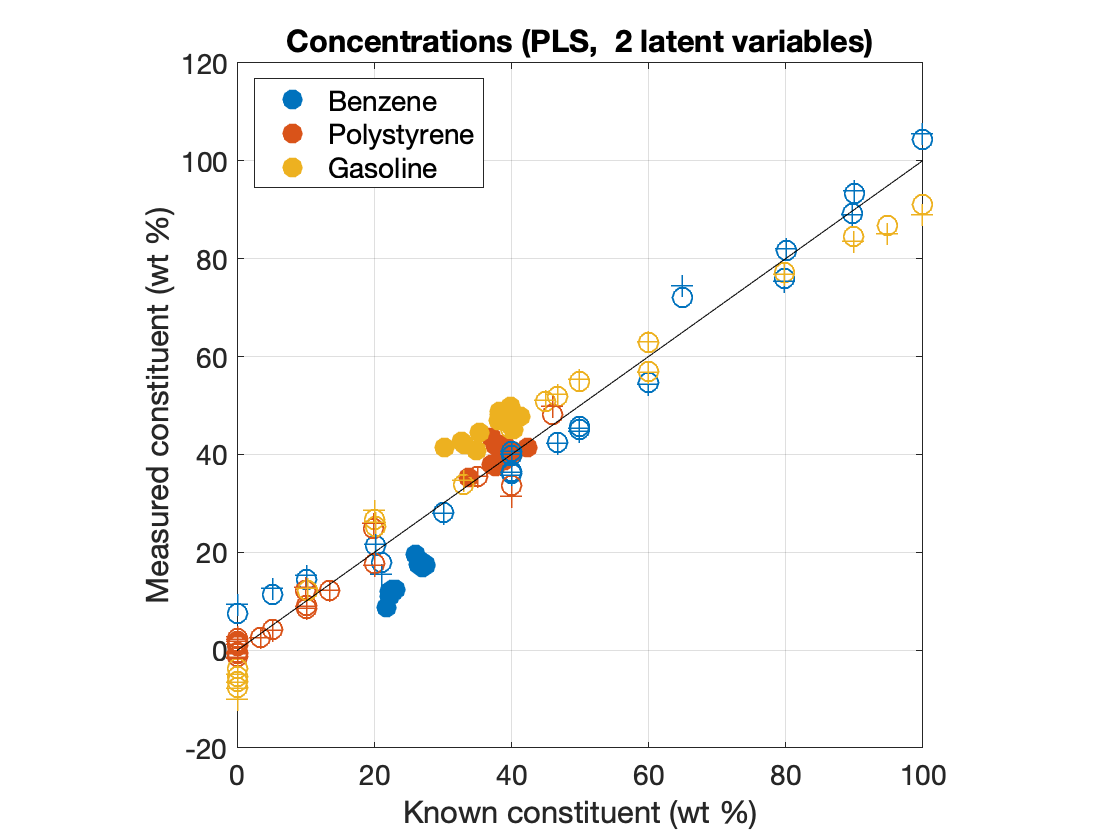

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  2 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        4.1479         2.296        5.5014
                    RMSECV        5.0229         2.924        6.5258
                     RMSEP        10.164        2.4566        8.8266
--------------------------------------------------------------------


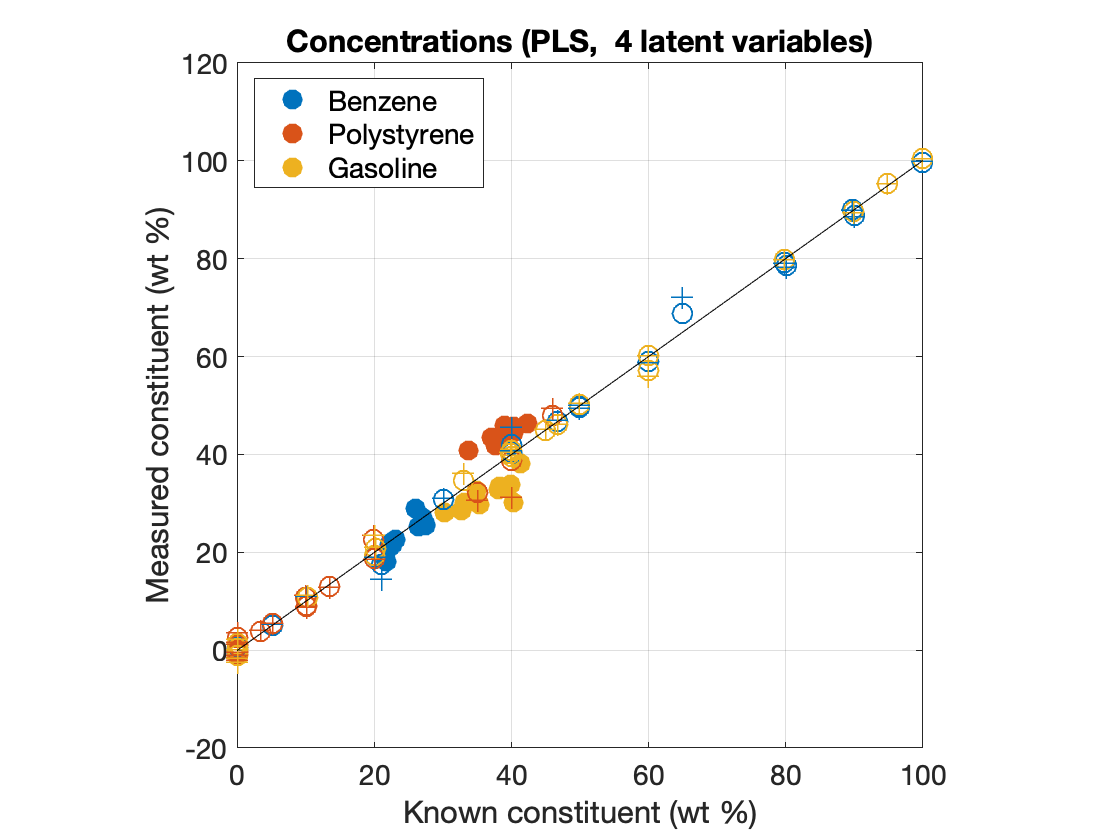

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  4 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        1.3963        1.3754       0.94211
                    RMSECV        2.6054        2.7754        1.6862
                     RMSEP         1.692        5.7011         5.157
--------------------------------------------------------------------


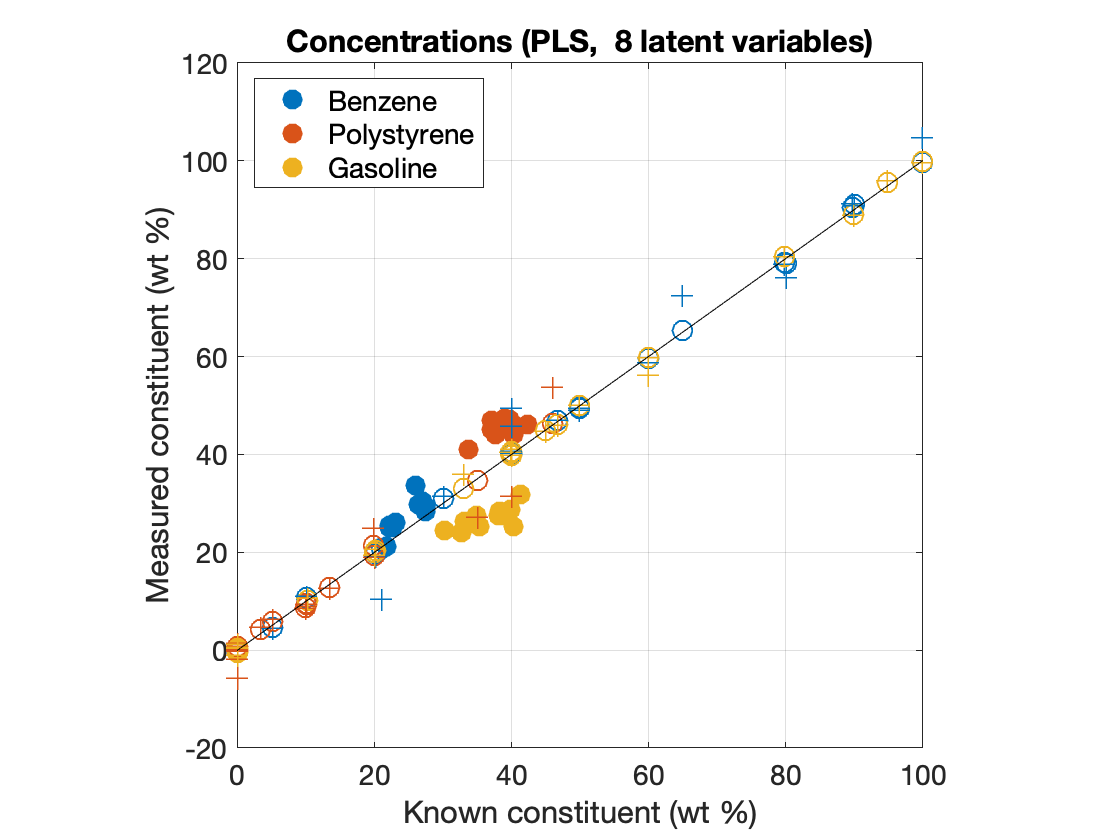

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  8 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC       0.55266       0.64849        0.3842
                    RMSECV        4.1383        3.7088        1.2699
                     RMSEP        3.3601        7.1028        9.9981
--------------------------------------------------------------------


meanCentered = true;
pnnl_napalm_pls([2 4 8], meanCentered);

### Output Data

The computed data are returned if you call the functions with output arguments, and the plot and display are suppressed.

## Optimal number of principal components for PCR with the napalm data

Compute PCR for 1 through 18 principal components and plot RMSEP for them.

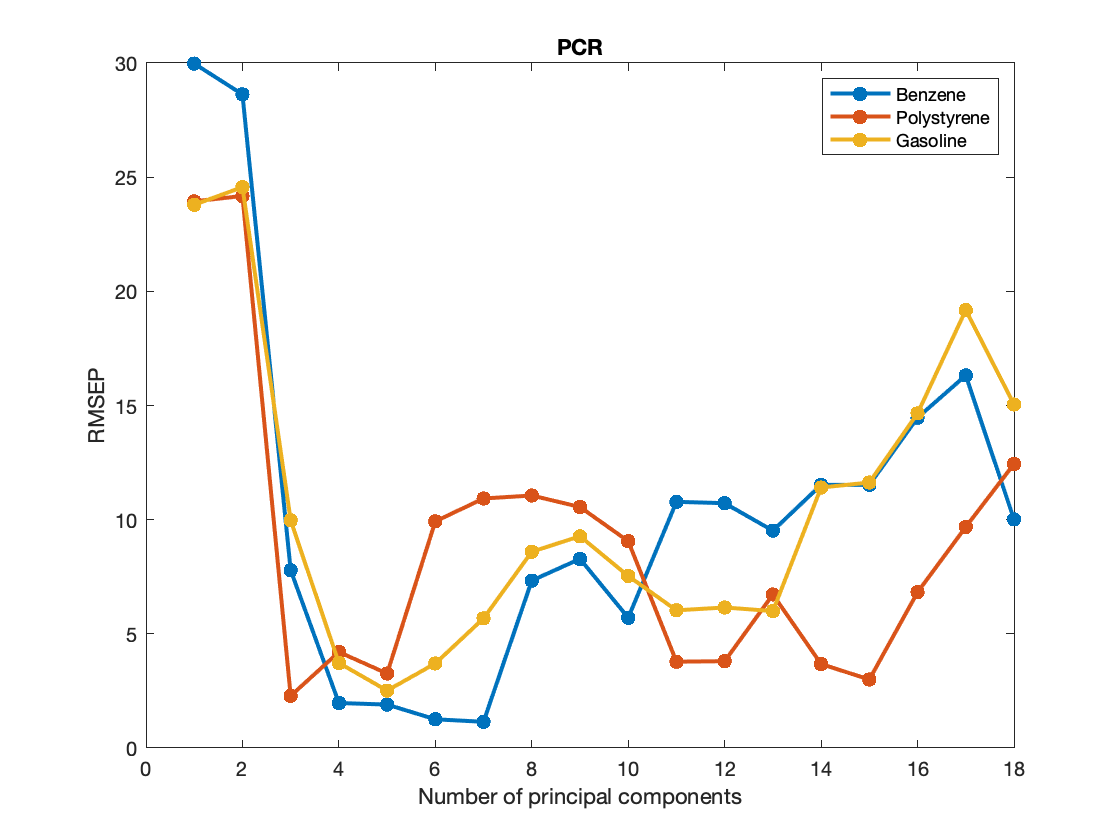

nPrincipalComponents = 1:18;
[C_pcr, RMSEP_pcr] = pnnl_napalm_pcr(nPrincipalComponents);
plot(nPrincipalComponents, RMSEP_pcr,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of principal components')
ylabel('RMSEP')
title('PCR')
legend(ConstituentNames{:})

It looks like 3 is the knee in the curve for polystyrene and 4 for benzene and gasoline, with 7 being better for benzene and 5 being better for gasoline.  It may be best to use 4 principal components across the board, but visualize 4, 7, and 5 to see what they look like.

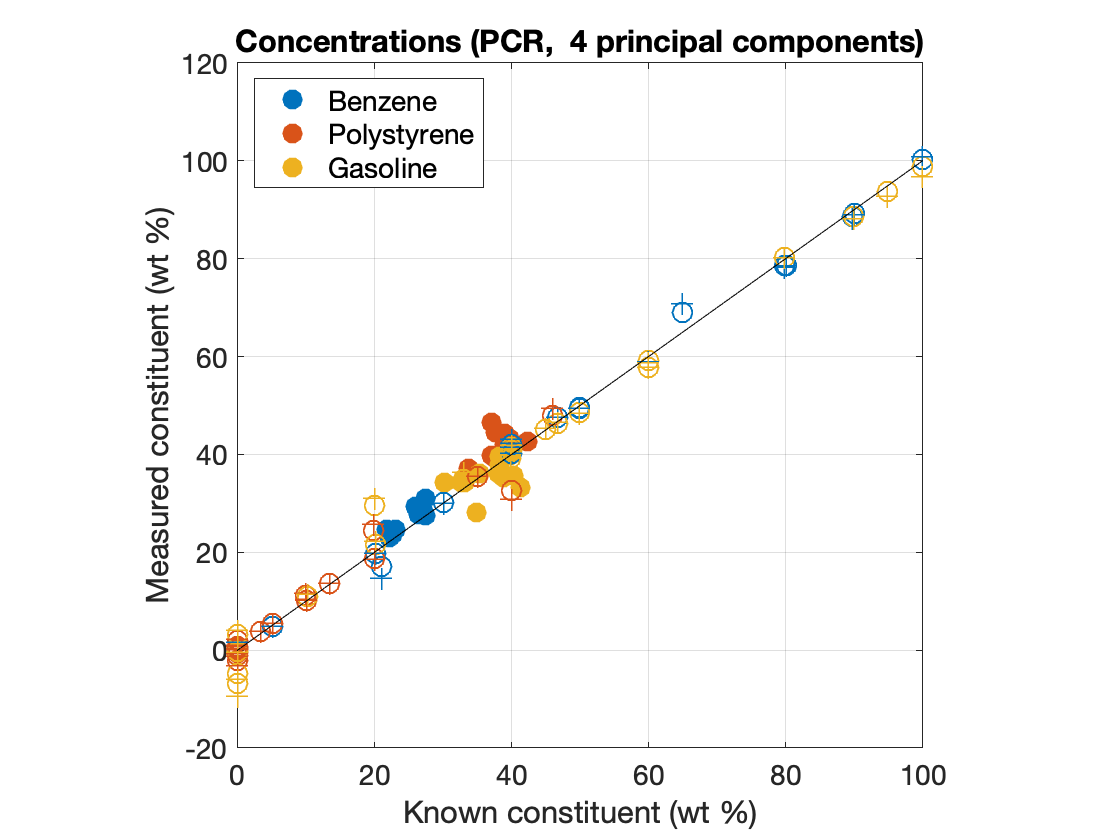

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
------------------------------------------------------------------------
  PCR,  4 principal components       Benzene   Polystyrene      Gasoline
                         RMSEC        1.5239        2.1479        3.0752
                        RMSECV        2.3196        2.7733        3.9613
                         RMSEP        1.9709        4.2039        3.7242
------------------------------------------------------------------------


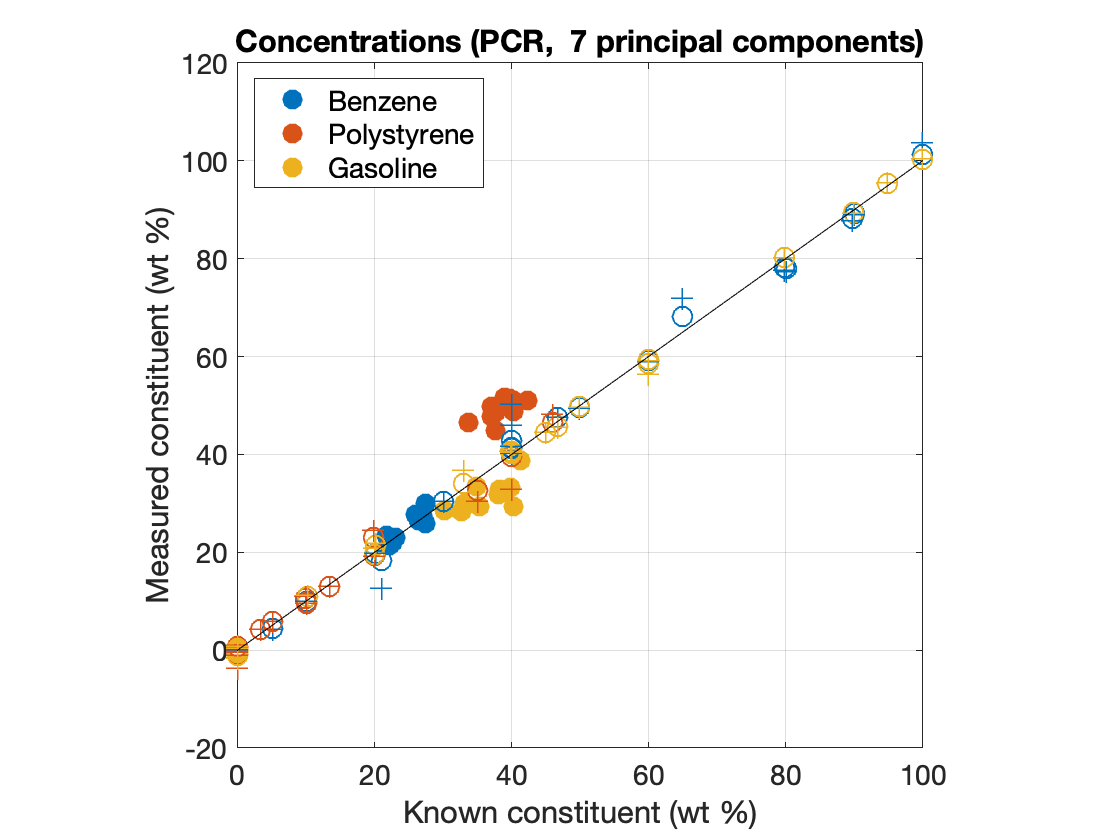

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
------------------------------------------------------------------------
  PCR,  7 principal components       Benzene   Polystyrene      Gasoline
                         RMSEC        1.4425        1.0488       0.72249
                        RMSECV        3.8273        2.4622        1.4638
                         RMSEP        1.1476        10.928        5.6779
------------------------------------------------------------------------


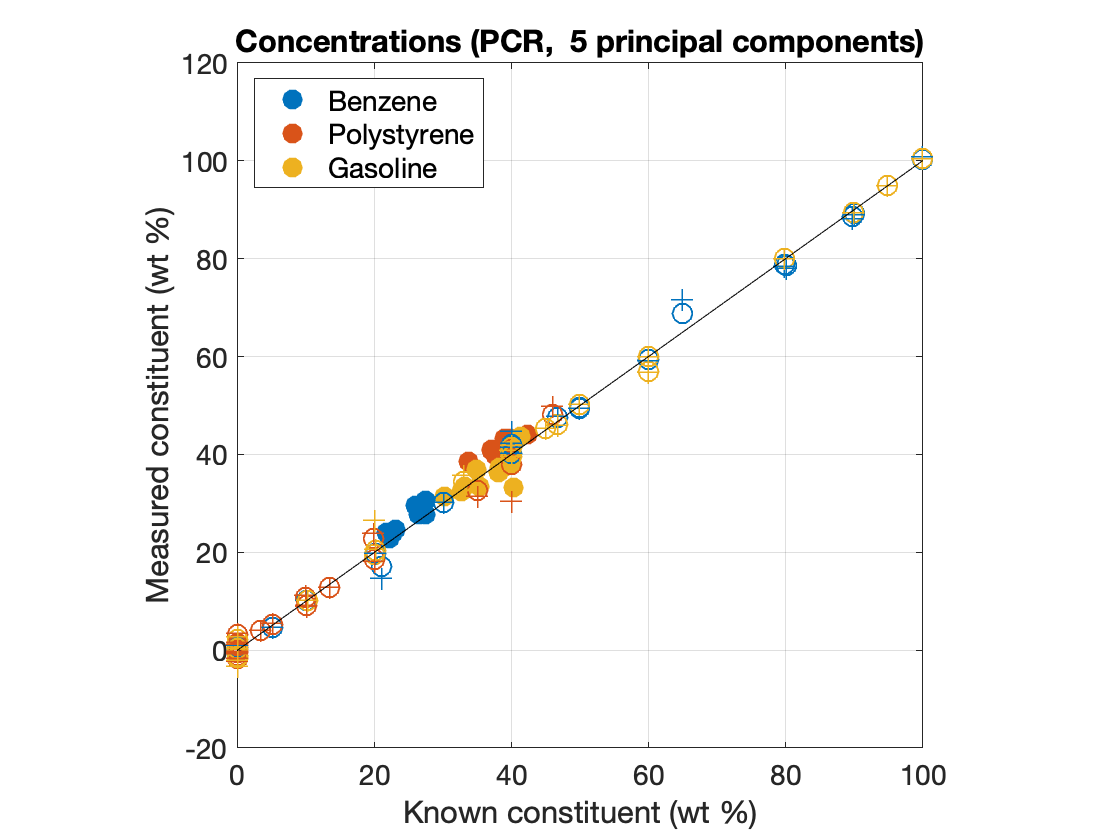

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
------------------------------------------------------------------------
  PCR,  5 principal components       Benzene   Polystyrene      Gasoline
                         RMSEC         1.518        1.5102        1.1154
                        RMSECV        2.5405        2.8788        2.1064
                         RMSEP        1.9013        3.2618        2.5142
------------------------------------------------------------------------


nPrincipalComponents = [4 7 5]; 
pnnl_napalm_pcr(nPrincipalComponents);

## Optimal number of latent variables for PLS with the napalm data

Compute PLS for 1 through 18 latent variables and plot RMSEP for them.

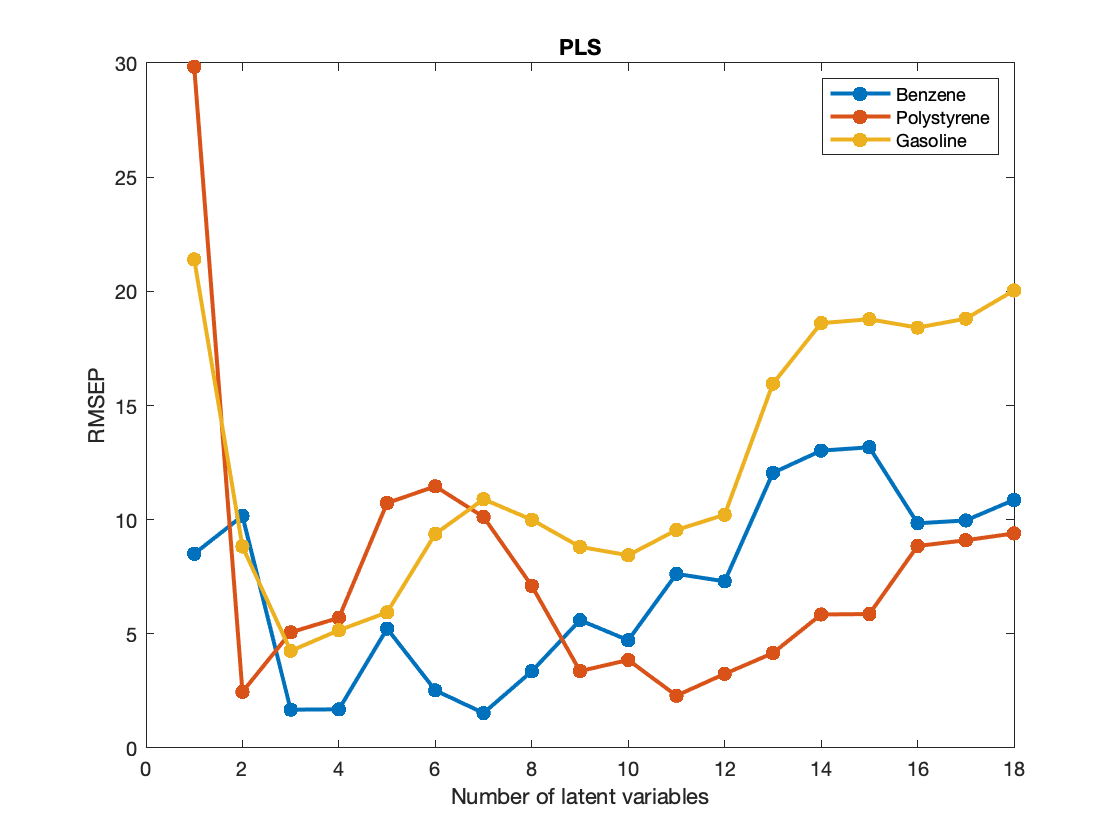

nLatentVariables = 1:18;
meanCentered = true;
[C_pls, RMSEP_pls] = pnnl_napalm_pls(nLatentVariables, meanCentered);
plot(nLatentVariables, RMSEP_pls,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSEP')
title('PLS')
legend(ConstituentNames{:})

It looks like the knee in the curve for benzene and gasoline is 3 latent variables, and 2 for polystyrene.  Plot them to see what they look like.

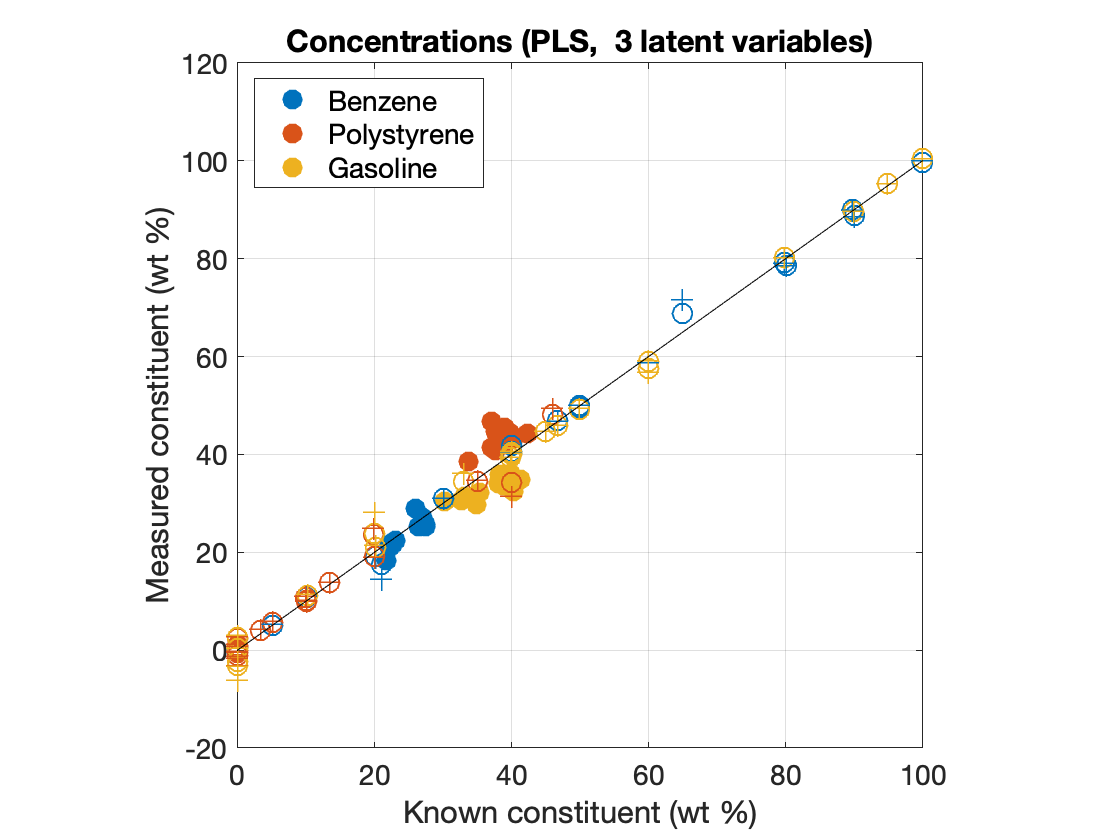

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  3 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        1.3968        1.8465        1.5789
                    RMSECV        2.2406        2.6176        2.7657
                     RMSEP        1.6799        5.0647        4.2528
--------------------------------------------------------------------


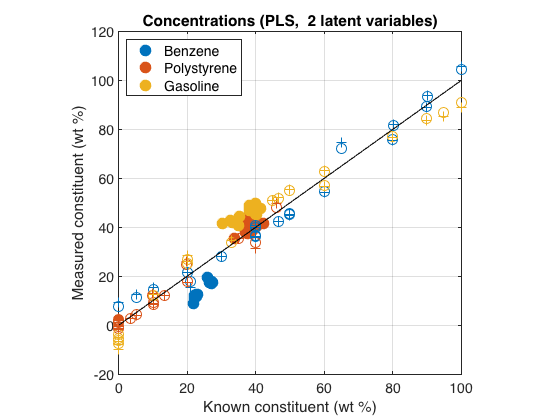

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  2 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        4.1479         2.296        5.5014
                    RMSECV        5.0229         2.924        6.5258
                     RMSEP        10.164        2.4566        8.8266
--------------------------------------------------------------------


nLatentVariables = [3 2];
meanCentered = true;
pnnl_napalm_pls(nLatentVariables,meanCentered);

# Single Constituent Analysis

## Single-Constituent Analysis Function

Loop over one constituent at a time for a range of number of principal components for PCR or latent variables for PLS

where

or

## PCR single-constituent analysis

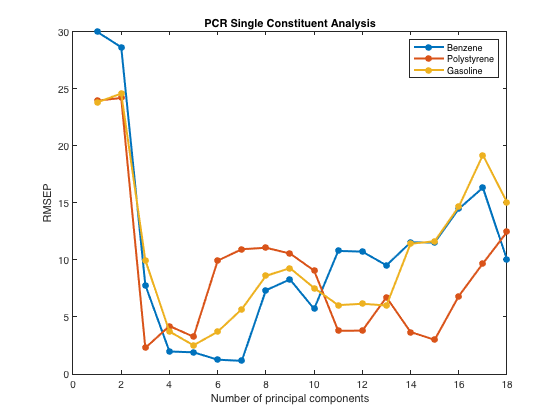

nPrincipalComponents = 1:18;
[C_pcr_single,RMSEP_pcr_single,C_pcr_train,RMSEC_pcr_single,C_pcr_cross_validation,RMSECV_pcr_single] = pnnl_single_constituent_analysis(@pnnl_pcr,A_train,C_train,A_unknown,C_validation,nPrincipalComponents);

figure
plot(nPrincipalComponents, RMSEP_pcr_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of principal components')
ylabel('RMSEP')
title('PCR Single Constituent Analysis')
legend(ConstituentNames{:})

RMSEP_pcr_single

RMSEP_pcr_single =    29.9750   23.9417   23.7927
   28.6263   24.1762   24.5626
    7.7847    2.2831    9.9695
    1.9709    4.2039    3.7242
    1.9013    3.2618    2.5142
    1.2574    9.9258    3.7027
    1.1476   10.9276    5.6779
    7.3318   11.0582    8.5945
    8.2835   10.5548    9.2745
    5.7046    9.0578    7.5328


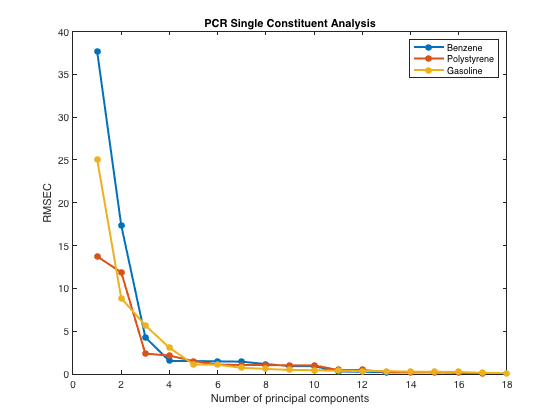

figure
plot(nPrincipalComponents, RMSEC_pcr_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of principal components')
ylabel('RMSEC')
title('PCR Single Constituent Analysis')
legend(ConstituentNames{:})

RMSEC_pcr_single

RMSEC_pcr_single =    37.7112   13.7234   25.0924
   17.3697   11.8892    8.8694
    4.2787    2.3856    5.6681
    1.5239    2.1479    3.0752
    1.5180    1.5102    1.1154
    1.4748    1.1014    1.0794
    1.4425    1.0488    0.7225
    1.1541    1.0486    0.5920
    0.9278    1.0113    0.4704
    0.9120    1.0066    0.4550


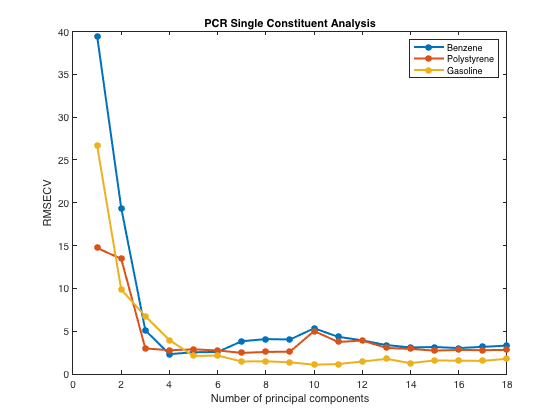

figure
plot(nPrincipalComponents, RMSECV_pcr_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of principal components')
ylabel('RMSECV')
title('PCR Single Constituent Analysis')
legend(ConstituentNames{:})

RMSECV_pcr_single

RMSECV_pcr_single =    39.4672   14.7174   26.6809
   19.3866   13.4528    9.8643
    5.1022    2.9924    6.7526
    2.3196    2.7733    3.9613
    2.5405    2.8788    2.1064
    2.5757    2.7548    2.1532
    3.8273    2.4622    1.4638
    4.0755    2.5793    1.4817
    4.0295    2.6122    1.3666
    5.3362    5.0141    1.0877


## PLS single-constituent analysis (PLS1)

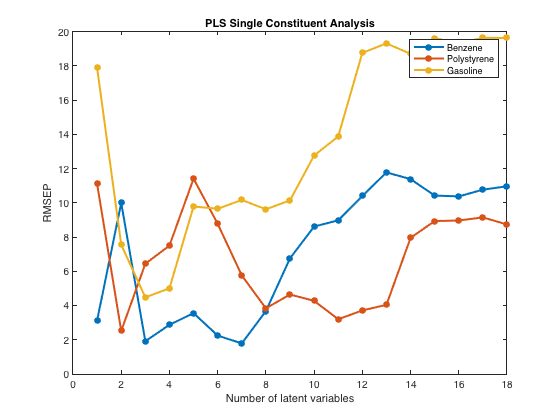

nLatentVariables = 1:18;
meanCentered = true;
[C_pls_single,RMSEP_pls_single,C_pls_train,RMSEC_pls_single,C_pls_cross_validation,RMSECV_pls_single] = pnnl_single_constituent_analysis(@pnnl_pls,A_train,C_train,A_unknown,C_validation,nLatentVariables,meanCentered);

figure
plot(nLatentVariables, RMSEP_pls_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSEP')
title('PLS Single Constituent Analysis')
legend(ConstituentNames{:})

RMSEP_pls_single

RMSEP_pls_single =     3.1308   11.0967   17.8789
    9.9863    2.5181    7.5506
    1.9121    6.4373    4.4750
    2.8748    7.4979    5.0049
    3.5529   11.4055    9.7827
    2.2445    8.7721    9.6469
    1.7867    5.7572   10.1628
    3.6749    3.8344    9.6194
    6.7532    4.6419   10.1391
    8.6112    4.2729   12.7604


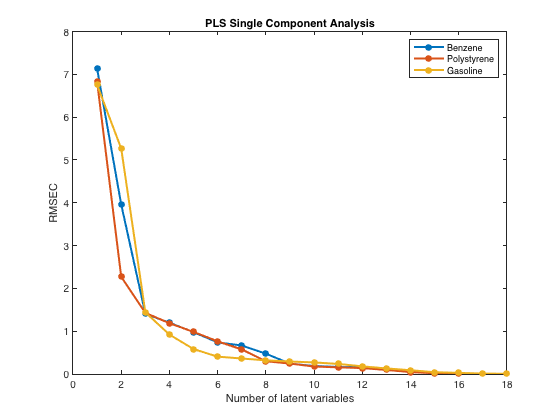


figure
plot(nLatentVariables, RMSEC_pls_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSEC')
title('PLS Single Component Analysis')
legend(ConstituentNames{:})

RMSEC_pls_single

RMSEC_pls_single =     7.1284    6.8256    6.7547
    3.9581    2.2700    5.2652
    1.4067    1.4287    1.4405
    1.1976    1.1857    0.9208
    0.9781    0.9835    0.5819
    0.7375    0.7626    0.4047
    0.6659    0.5739    0.3629
    0.4745    0.2977    0.3193
    0.2418    0.2440    0.2915
    0.1866    0.1746    0.2706


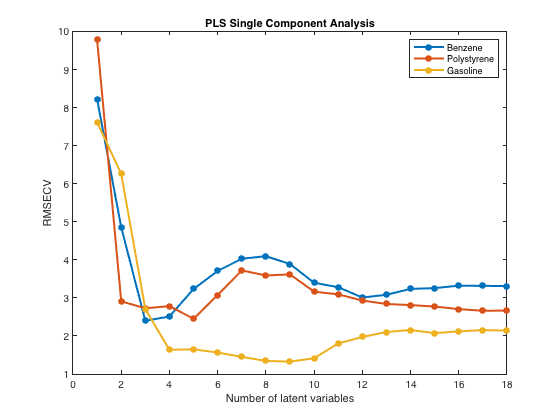

figure
plot(nLatentVariables, RMSECV_pls_single,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSECV')
title('PLS Single Component Analysis')
legend(ConstituentNames{:})

RMSECV_pls_single

RMSECV_pls_single =     8.2183    9.7797    7.6180
    4.8587    2.9092    6.2563
    2.3988    2.7267    2.7035
    2.5116    2.7840    1.6352
    3.2345    2.4518    1.6484
    3.7072    3.0753    1.5637
    4.0285    3.7219    1.4498
    4.0955    3.5892    1.3431
    3.8895    3.6171    1.3255
    3.3971    3.1633    1.4143


# Principal Components and Principal Component Scores

## Scores definition

The scores are the left-singular vectors multiplied by the singular values of the absorbance matrix. The economy-size singular value decomposition is


$$$$%
\underset{p\times m}{A} = %
\underset{p\times p}{U}\cdot\underset{p\times p}{\Sigma}\cdot\underset{p\times m}{V^\textrm{T}}%
$$$$


where $U$ and $V$ have orthonormal columns, $\Sigma = \textrm{diag}(\sigma_1,\, \sigma_2,\, \ldots \sigma_p)$, and $\sigma_1 \geq \sigma_2 \geq \cdots \sigma_p \geq 0$.

It can be written as a sum of rank-one outer products


$$$$%
\underset{p\times m}{A} = %
\sigma_1\underset{p\times 1}{U(\,:\,,1)}\underset{1\times m}{V(\,:\,,1)^\textrm{T}} +%
\sigma_2\underset{p\times 1}{U(\,:\,,2)}\underset{1\times m}{V(\,:\,,2)^\textrm{T}} +%
\cdots +%
\sigma_p\underset{p\times 1}{U(\,:\,,p)}\underset{1\times m}{V(\,:\,,p)^\textrm{T}}.%
$$$$


where $\sigma_iU(\,:\,,i)$ is called the score of the $i$ th principal component $V(\,:\,,i)$ ([Cleve Moler, "Professor SVD"](https://www.mathworks.com/company/newsletters/articles/professor-svd.html)).

In matrix form, this is written as

$$$%
\textrm{Scores} = U\Sigma
$$$.

## Singular Value Decomposition

Function `pnnl_rectifiedSVD` returns the economy-size singular value decomposition, where the maximum magnitude element of each column of V is positive, which is the convention for principal components.  The singular value decomposition is unique up to the signs of the columns of U and V, like `1*2*1 == -1*2*-1`.  Rectified singular value decompositions are unique, which makes it convenient to compare one score to another.

[U,S,V] = pnnl_rectifiedSVD(A_train);

## Principal Components

The principal components are the right singular vectors in the columns of matrix $V$. 

Plot the first four principal components.

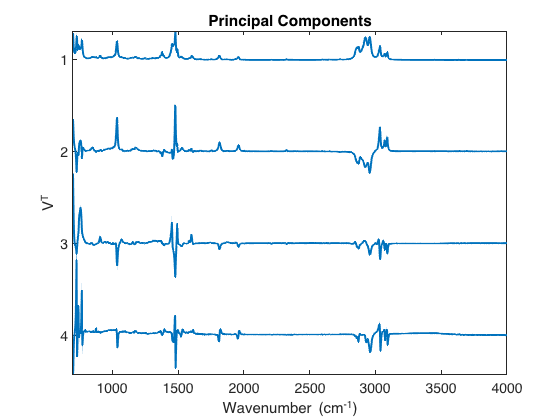

figure
pnnl_strip_plot(Wavenumbers,V(:,1:4)',...
    'Principal Components',...
    WavenumberLabel,'V^T');

## Principal Compent Scores

The scores are the left singular vectors multplied by the singular values.

Scores = U*S;

Plot the scores of one principal component against the other.

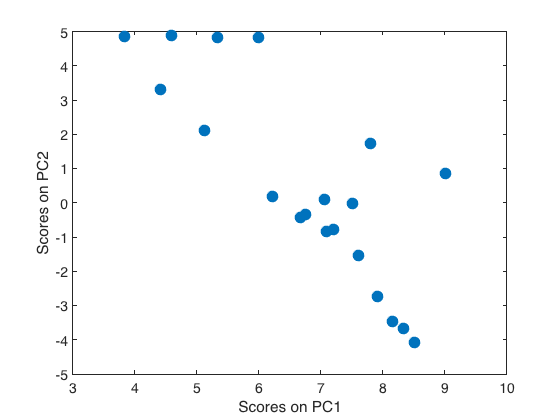

fontSize = 14;
plot(Scores(:,1),Scores(:,2),'.','MarkerSize',35);
xlabel('Scores on PC1');
ylabel('Scores on PC2');
set(gca,'FontSize',fontSize);
box on

## Plot scores with labels

The scores only rely on an absorbance matrix, without having to know the actual concentrations.  If you also know the concentrations, then you can use that information to label the scores.  Function `pnnl_plot_scores` computes and plots the scores as in the previous section, and also uses information in the known concentrations to label the scores plot.

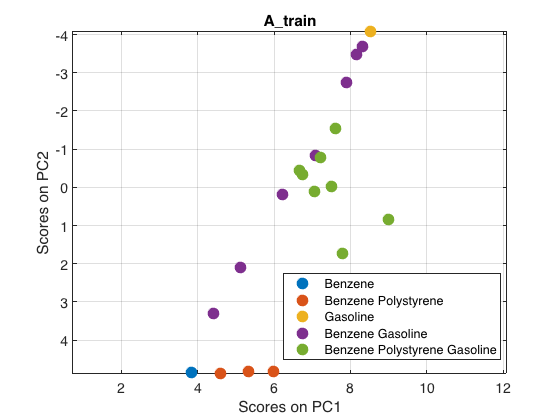

pnnl_plot_scores(A_train, C_train, 1, 2, ConstituentNames)

## Display concentration percentages of training set

If you input an additional parameter to `pnnl_plot_scores`, then it will also display the concentration percentages as (%benzene, %polystyrene, %gasoline), which may be useful to zoom in and explore the linear relationship between the scores.

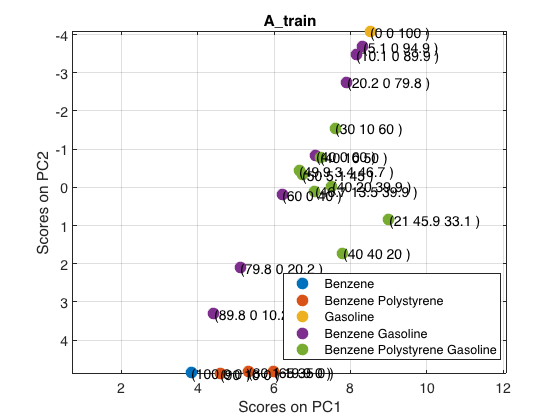

displayConcentrations = true;
pnnl_plot_scores(A_train, C_train, 1, 2, ConstituentNames, displayConcentrations)

## Display concentration percentages of unknown set

If you input an additional parameter to `pnnl_plot_scores`, then it will also display the concentration percentages as (%benzene, %polystyrene, %gasoline), which may be useful to zoom in and explore the linear relationship between the scores.

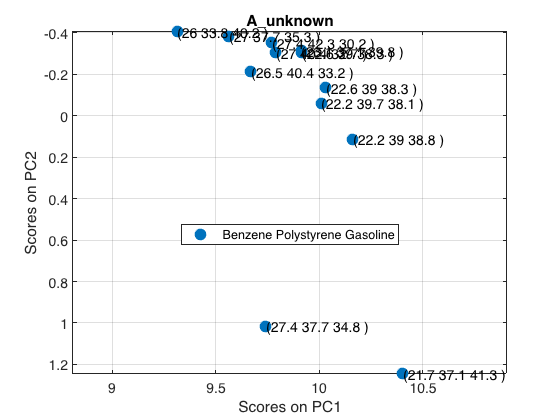

displayConcentrations = true;
pnnl_plot_scores(A_unknown, C_validation, 1, 2, ConstituentNames, displayConcentrations)

## Display all combinations of scores

Function `pnnl_napalm_plot_scores` loads the napalm data set and loops over all combinations of principal components.

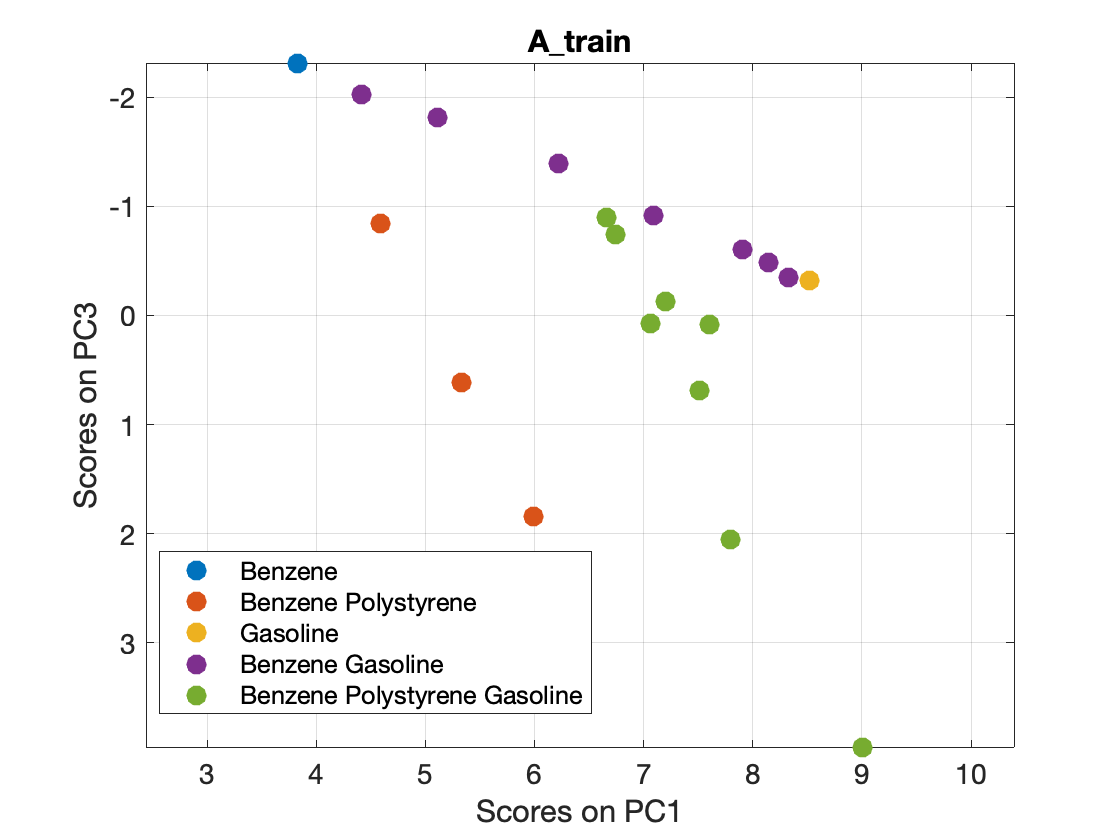

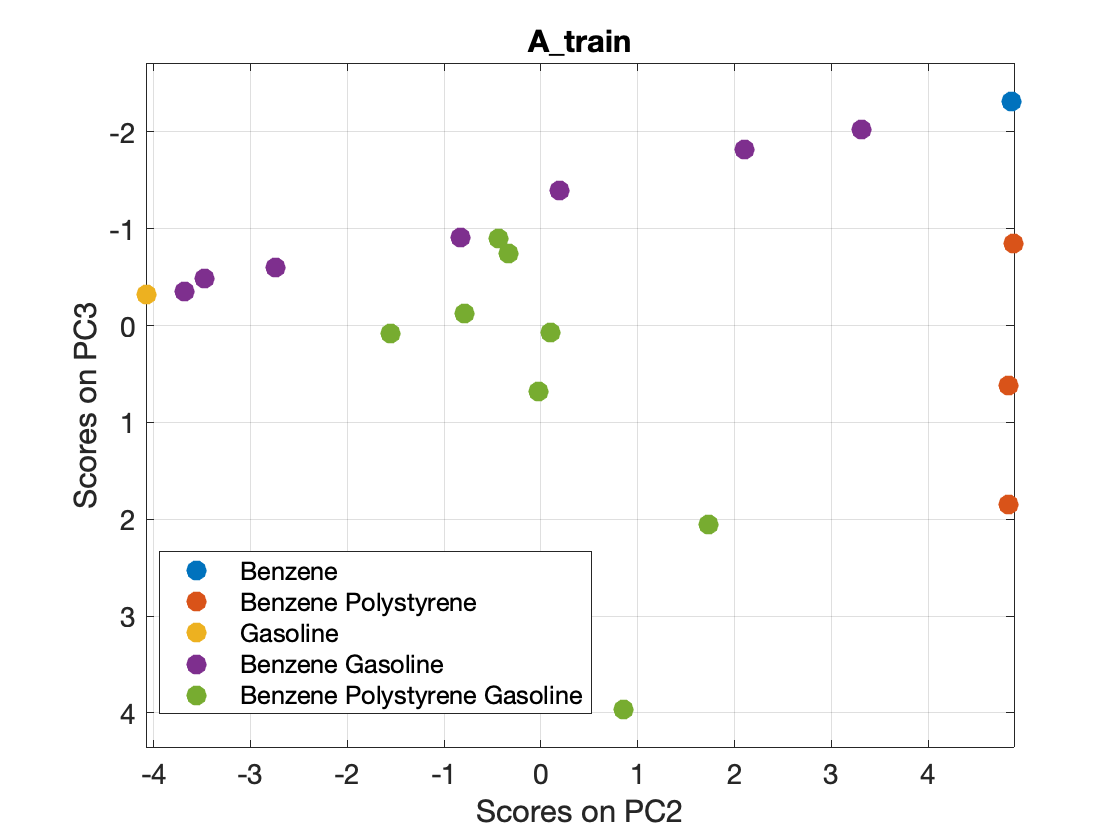

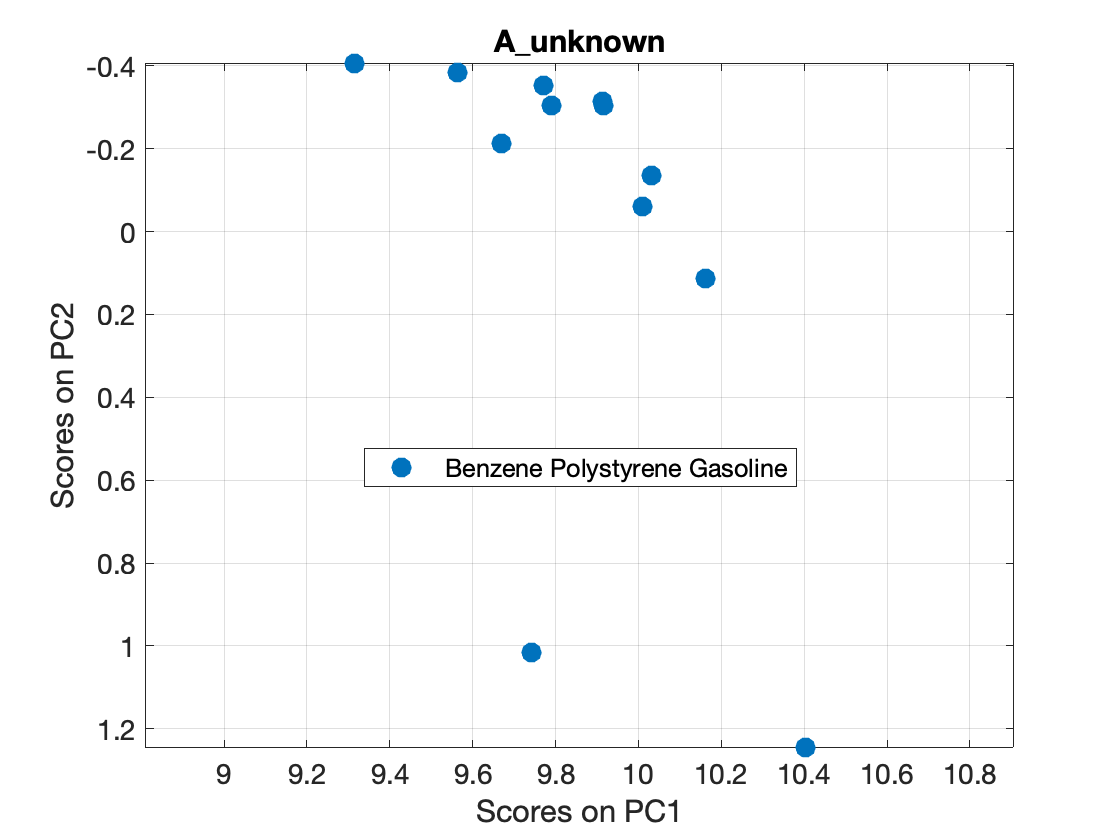

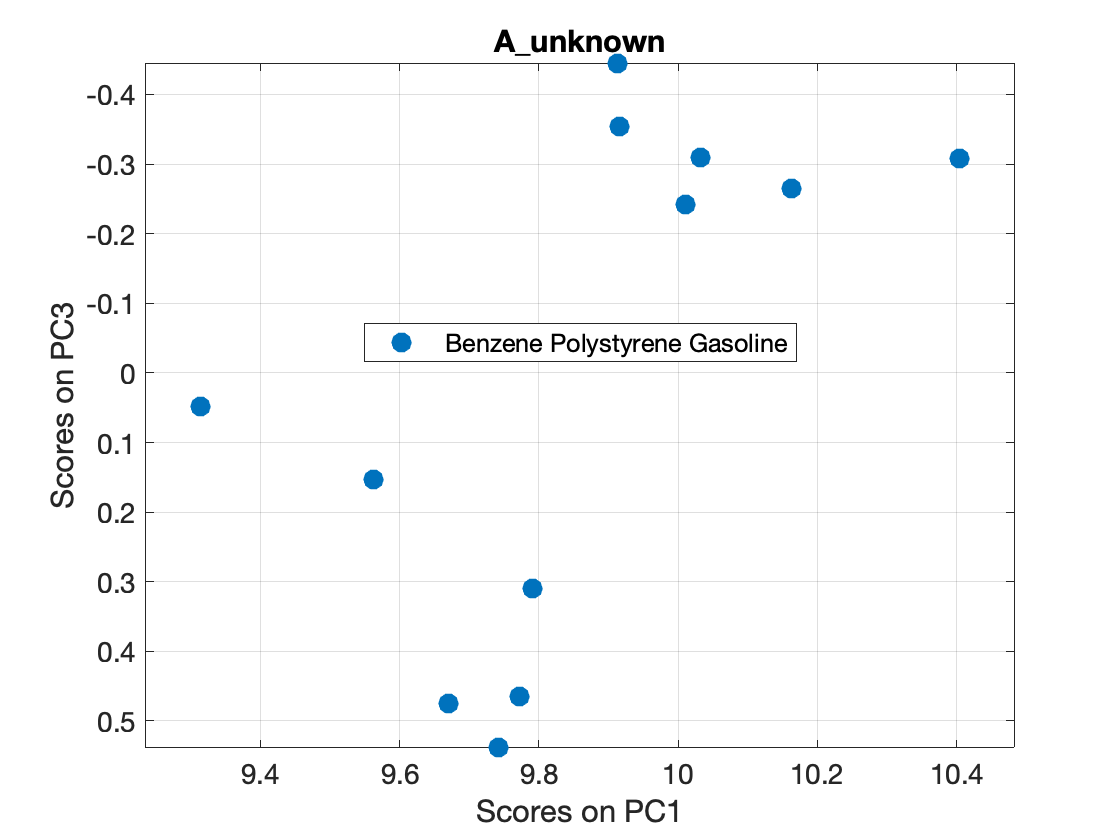

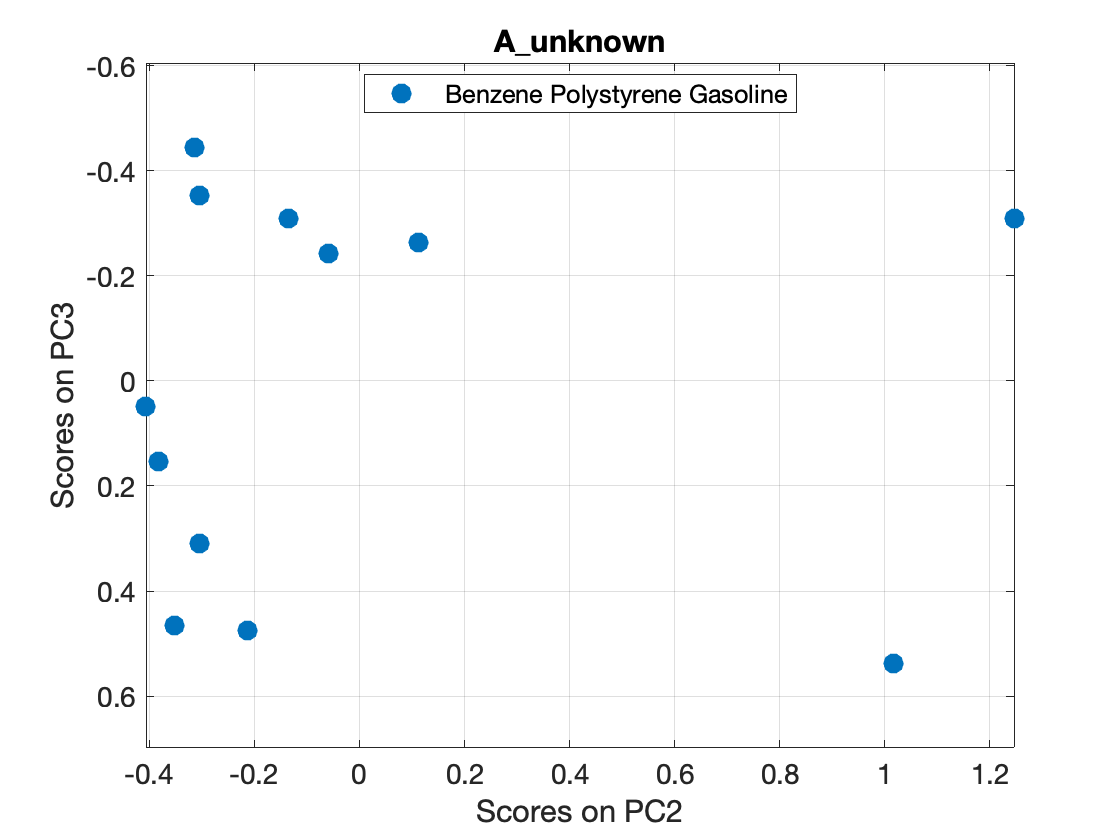

pnnl_napalm_plot_scores

# Spectra

## Measured spectra

The `pnnl_napalm_plot_spectra` function plots the napalm spectra meaasured in $A_\textrm{train}$ and $A_\textrm{unknown}$.

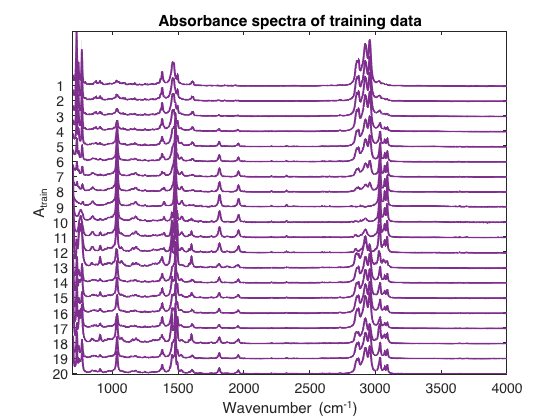

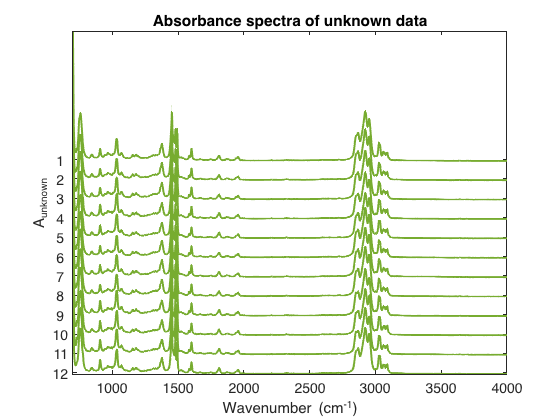

pnnl_napalm_plot_spectra

## CLS K vs Pure Spectra

Classical least squares computes $C_\textrm{cls}$ that minimizes $||CK-A||_2$, where $CK=A$ is the Beer's law relationship between concentration $C$, extinction coefficient $K$ and absorbtion $A$.  An estimation of the extinction coefficient matrix $K_\textrm{cls}$ is computed as a byproduct of the CLS method.  

You can see in the following plots that the rows of $K_\textrm{cls}$ match the spectra of the pure constituents.

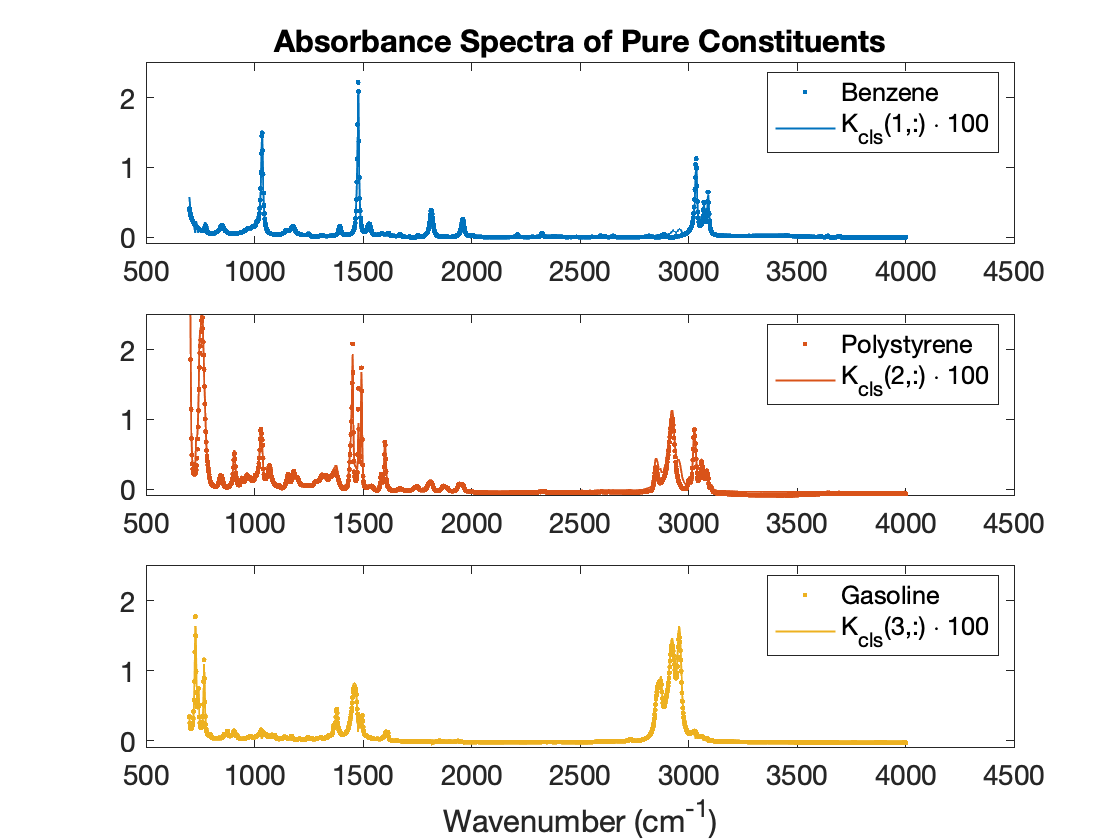

[C_cls, B_cls, K_cls] = pnnl_cls(A_train, C_train, A_unknown);
pnnl_napalm_plot_pure_spectra_vs_K_cls

# Ternary plot

You can see the overlap between $C_\textrm{train}$ and $C_\textrm{validation}$ concentraions by plotting them in a ternary plot.

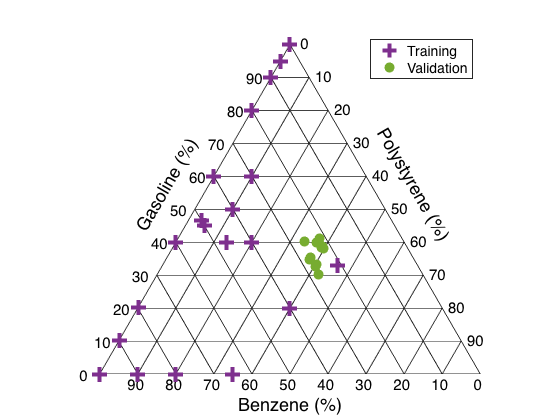

pnnl_napalm_plot_concentration_ternary

# Glossary

## Methods

- Classical Least Squares (CLS)

- Principal Component Regression (PCR)

- Partial Least Squares (PLS)

## Numbers

- $m$ is the number of measured wavenumbers.  In the napalm data, $m=1713$.

- $n$ is the number of constituents.  In the napalm data, $n=3$ for constituents benzene, polystyrene, and gasoline.

- $p$ is the number of compounds.  In the napalm data, $p_\textrm{train}=20$ for the training compounds, and $p_\textrm{unknown}=12$for the unknown compounds.

- $r$ is the number of principal components in PCR, and the number of latent variables in PLS.

## Matrices

- $A$ is a matrix of absorbance spectra

- $C$ is a matrix of concentrations

- $K$ is a matrix of normalized extinction coefficients

## Specific Matrices

- $A_\textrm{train}$ is the measured absorbance matrix from the training solutions.

- $A_\textrm{unknown}$ is the measured absorbance matrix from the solution with unknown concentrations

- $C_\textrm{train}$ is the matrix of known concentrations (measured into the solution)

- $C_\textrm{validation}$ is the matrix of concentrations of the unknown solution derived by an independent means

- $C_\textrm{cls}$, $C_\textrm{pcr}$, $C_\textrm{pls}$ is the concentration matrix of the unknown solution computed using CLS, PCR, PLS respectively

- $K_\textrm{cls}$, $K_\textrm{pcr}$, $K_\textrm{pls}$ is the matrix of normalized extinction coefficients computed using CLS, PCR, PLS respectively

## Root Mean Square Error

- $\textrm{RMSE} = \textrm{pnnl\_rmse}(C_\textrm{computed},C_\textrm{known}) = \sqrt{\textrm{mean}\left((C_\textrm{computed}-C_\textrm{known}).^2\right)}$. Root mean square error between a computed value and a known value. 

- $\textrm{RMSEP} = \textrm{pnnl\_rmse}(C_\textrm{predicted}, C_\textrm{validation})$. RMSEP is the prediction error measured on real cases and compared to reference values.

- $\textrm{RMSEC} = \textrm{pnnl\_rmse}(C_\textrm{predicted from train}, C_\textrm{train})$. RMSEC is the calibration error.  $C_\textrm{predicted from train}$ is computed by using $A_\textrm{train}$ as the unknown.

- $\textrm{RMSECV} = \textrm{pnnl\_rmse}(C_\textrm{cross validation}, C_\textrm{train})$.   RMSECV is the cross-validation error. For each of the rows in the training set $C_\textrm{train}$ and $A_\textrm{train}$, leave one row out, and use that row as the unknown data in the predictor.  Store the result in $C_\textrm{cross-validation}$.  Then compute the RMSE between $C_\textrm{cross validation}$ and $C_\textrm{train}$.

# Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830